**DARPA SUBOFF AXISYMMETRIC HULL**

The axisymmetric hull has an overall length of 14.291667 Ft (4.356 m) and a maximum diameter of 1.666667 Ft (0.508 m).

x = Model Scale Axial Length in Feet

R = Model Scale Radial Length in Feet

Forebody Length = 3.333333 Ft (1.016 m)

Parallel Middle Body Length = 7.3125 Ft (2.229 m)

Afterbody Length = 3.645833 Ft (1.111 m)

Aft Perpendicular at x = 13.979167 Ft (4.461 m)

Total Body Length = 14.291666 (4.356 m)

Maximum Body Diameter = 1.666667 Ft (0.508 m)

Lamda = (FULL/MODEL) SCALE RATIO = 24

**Main Dimensions**

% DARPA SUBOFF AXISYMMETRIC HULL

% Define dimensions

L_total_ft = 14.291667; % Total length in feet
D_max_ft = 1.666667; % Maximum diameter in feet
Rmax = 5 / 6; % Maximum radius in feet
L_forebody_ft = 3.333333; % Forebody length in feet
L_parallel_middle_ft = 7.3125; % Parallel middle body length in feet
L_afterbody_ft = 3.645833; % Afterbody length in feet
L_aft_perpendicular_ft = 13.979167; % Aft perpendicular at x = 13.979167 Ft in feet
D_model_scale_ratio = 24; % Lambda: (FULL/MODEL) SCALE RATIO = 24


**BOW EQUATlON**

% BOW EQUATION
%For 0 Ft < x < 3.333333 Ft

DivisionsBow=60;
StepBow = L_forebody_ft / DivisionsBow;
XBow = 0:StepBow:L_forebody_ft;
RBow = Rmax .* (((1.126395101 .* XBow .* (0.3 .* XBow - 1).^4)+...
       ((0.442874707 .* XBow.^2) .* (0.3 .* XBow - 1).^3)     +...
       (1 - ((0.3 .* XBow - 1).^4) .* (1.2 .* XBow + 1))).^(1 / 2.1));


**PARALLEL MIDDLE BODY EQUATION**

% PARALLEL MIDDLE BODY EQUATION
%For 3.333333 Ft <= x <= 10.645833 FtDivisionsParallel

DivisionsParallel=60;
StepParallel = (L_aft_perpendicular_ft - 2*L_forebody_ft) / DivisionsParallel;
XParallel = L_forebody_ft:StepParallel:L_aft_perpendicular_ft-L_forebody_ft;
RParallel = ones(1, DivisionsParallel + 1) * Rmax;

**AFTERBODY EQUATION**

% AFTERBODY EQUATION
% For 10.645833 Ft <= x <= 13.979167 Ft

DivisionsAft =60;
StepAft = (L_aft_perpendicular_ft - (L_parallel_middle_ft+L_forebody_ft)) / DivisionsAft;
XAft = L_parallel_middle_ft+L_forebody_ft:StepAft:L_aft_perpendicular_ft;
e = ((L_aft_perpendicular_ft - XAft) / L_forebody_ft);
Rh = 0.1175;
K0 = 10;
K1 = 44.6244;
RAft = Rmax .* (((Rh^2 + Rh * K0 * e.^2) + ...
       (20 - 20 * Rh^2 - 4 * Rh * K0 - (1/3) * K1) * e.^3 + ...
       (-45 + 45 * Rh^2 + 6 * Rh * K0 + K1) * e.^4 + ...
       (36 - 36 * Rh^2 - 4 * Rh * K0 - K1) * e.^5 + ...
       (-10 + 10 * Rh^2 + Rh * K0 + (1/3) * K1) * e.^6)).^0.5;
  

**AFTERBODY CAP EQUATION**

% AFTERBODY CAP EQUATION
%For 13.979167 Ft <= x <= 14.291667 Ft

DivisionsAftCap=60;
StepAftCap = (L_total_ft - L_aft_perpendicular_ft) / DivisionsAftCap;
XAftCap = L_aft_perpendicular_ft:StepAftCap:L_total_ft;
RAftCapTotal = 0.1175 .* Rmax .* (1 - (3.2 .* XAftCap - 44.733333) .^ 2) .^ 0.5;
RAftCap=real(RAftCapTotal);

**Plotting Profile & 3D Surface**

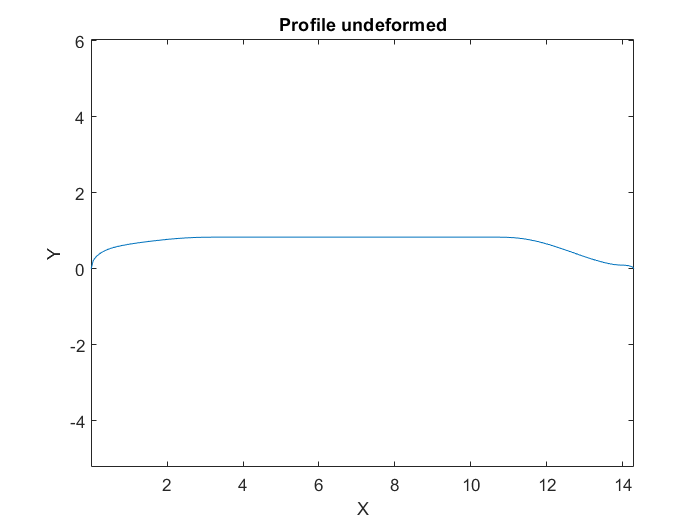

% Define the curve
% x_curve = [XBow XParallel] % X-coordinates of the curve
% y_curve = [RBow RParallel] % Corresponding Y-coordinates of the curve
x_curve = [XBow XParallel XAft XAftCap]; % X-coordinates of the curve
y_curve = [RBow RParallel RAft RAftCap];% Corresponding Y-coordinates of the curve

% Plot the curve
plot(x_curve, y_curve);
xlabel('X');
ylabel('Y');
title('Profile undeformed');
axis equal;

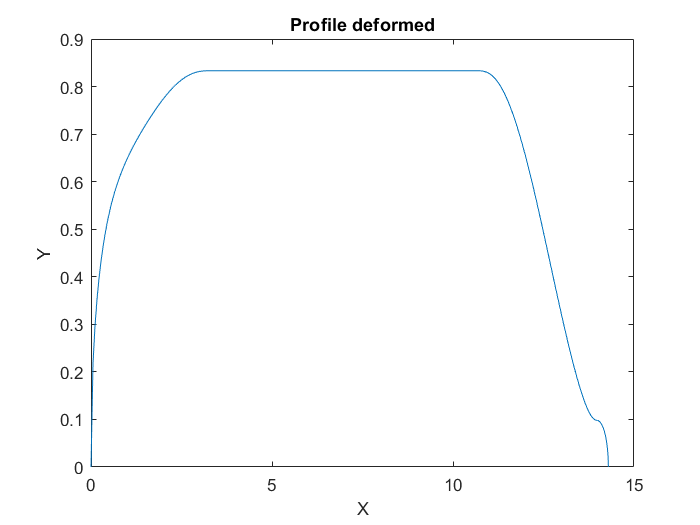

plot(x_curve, y_curve);
xlabel('X');
ylabel('Y');
title('Profile deformed');

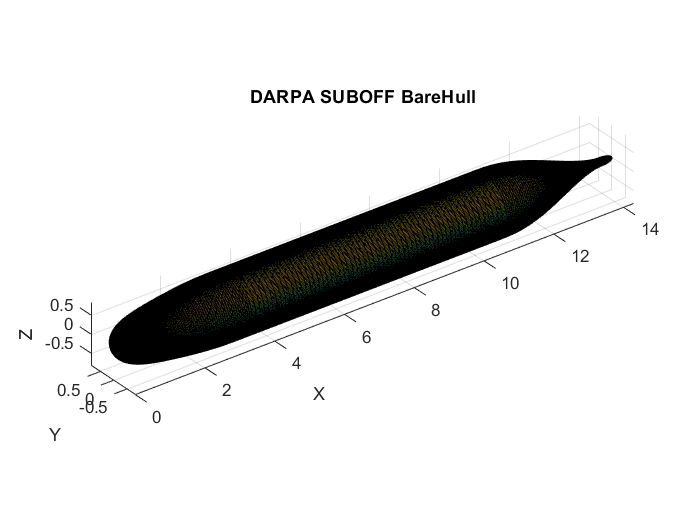

% Generate surface coordinates by revolving the curve around the x-axis
numPoints = numel(x_curve); % Number of points in the curve
numTheta = 180; % Number of points around the circle (adjust as needed)

theta = linspace(0, 2*pi, numTheta); % Angular coordinates for rotation

% Initialize arrays for surface coordinates
X = repmat(x_curve', 1, numTheta); % Repeat x_curve along columns
Y = y_curve' * cos(theta); % Revolve y_curve around the x-axis
Z = y_curve' * sin(theta); % Revolve y_curve around the x-axis

% Plot the surface
figure;
surf(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('DARPA SUBOFF BareHull');
axis equal;

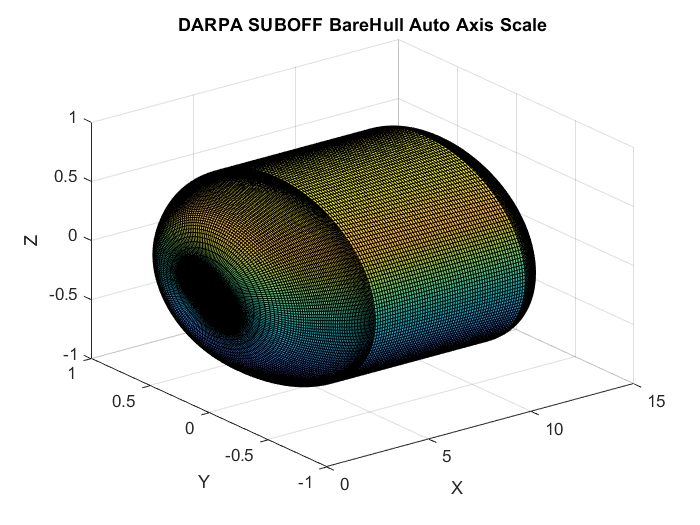

% Plot the surface
figure;
surf(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('DARPA SUBOFF BareHull Auto Axis Scale');